# Project 4 - Jib & Trolley Kinematics and Lagrange's Equation

#### This script derives the Lagrange's equations for three generalized coordinates which are Euler angles $\phi, \theta, \psi$ for the system shown in the project description.

#### First of all, we will write down the single axis rotation matrices which will be reference for deriving the equations.

For rotation around X-axis:


$$R_x(\alpha) = \left[ \matrix{1 & 0 & 0 \cr 0 & \cos(\alpha) & \sin(\alpha) \cr 0 & -\sin(\alpha) & \cos(\alpha) }\right]$$


For rotation around Y-axis:


$$R_y(\alpha) = \left[ \matrix{\cos(\alpha) & 0 & -\sin(\alpha) \cr 0 & 1 & 0 \cr \sin(\alpha) & 0 & \cos(\alpha) }\right]$$


For rotation around Z-axis:


$$R_z(\alpha) = \left[ \matrix{\cos(\alpha) & \sin(\alpha) & 0 \cr -\sin(\alpha) & \cos(\alpha) & 0 \cr 0 & 0 & 1 }\right]$$


We extract the angular velocity ${}^b{\vec{\omega}_b$ from a rotation matrix using:


$${}^b\Omega_b = {}^b_a R \,\,{}^a_b\dot{R}$$


and we extract the components of ${}^b \vec{\omega}_b$ from the spin tensor as


$${}^b \Omega_b = \left[ \matrix{0 & -\omega_z & \omega_y \cr \omega_z & 0 & -\omega_x \cr -\omega_y & \omega_x & 0 } \right]$$


#### Now, we will draw the diagram of the multibody system with different frames mentioned on it for which we need to derive the differential equations.

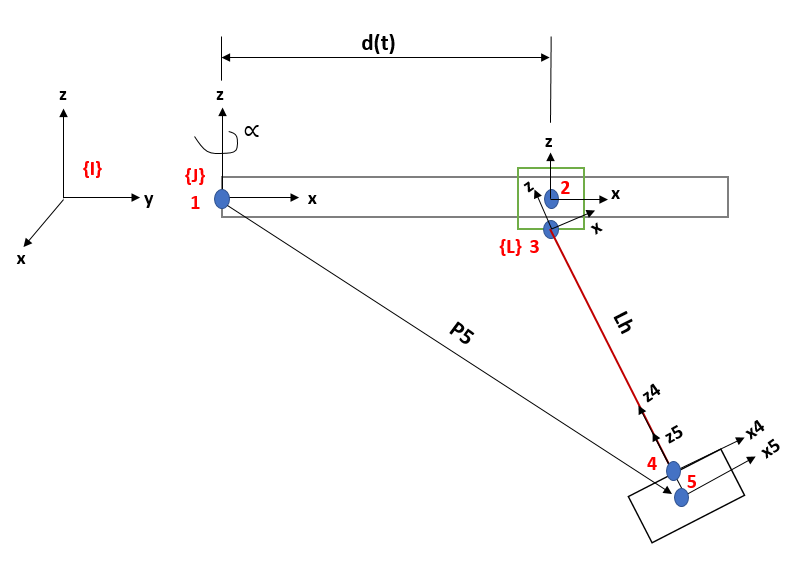

As with implementing Lagrange's Equation using LiveScript, we'll need to move back and forth between functions of time and symbols. So, we'll need to create to arrays that containt the quantities that we'll substitute back and forth.

First, we'll define all the variables used.

clearvars;
t = sym('t','real');   % time (s)
sympref('default');

% Constant parameters
syms m g Ixx Iyy Izz ht; % define these constant parameters. ht = height of the trolley. Ixx, Iyy & Izz are the mass moment of inertia of the load. m is the mass of the load.

% Generalized coordinate states
syms phiT(t) thtT(t) psiT(t) ;  % define names of three euler angles in time variable
syms phiS    thtS    psiS    ;  % define names of three euler angles in symbolic variable
syms phidS   thtdS   psidS   ;  % define names of first derivative of three euler angles in symbolic variable
syms phiddS  thtddS  psiddS  ;  % define names of second derivative of three euler angles in symbolic variable

% Attachment point states
syms xT(t) yT(t) LhT(t) ;  % define the x y & z motion of attachment point in time variable
syms xS    yS    LhS ;     % define the x y & z motion of attachment point in symbolic variable
syms xdS   ydS   LhdS ;    % define names of first derivative of motions in symbolic variable
syms xddS  yddS  LhddS ;   % define names of second derivative of motions in symbolic variable

xdT   = diff(xT,t);    % Calculate velocity of attachment point in x-direction
ydT   = diff(yT,t);    % Calculate velocity of attachment point in y-direction
phidT = diff(phiT,t);  % Differentiate rotation angle phi
thtdT = diff(thtT,t);  % Differentiate rotation angle theta
psidT = diff(psiT,t);  % Differentiate rotation angle psi
LhdT = diff(LhT, t);   % Differentiate motion of load in z-axis

xddT   = diff(xdT,t); % Calculate acceleration of attachment point in x-direction
yddT   = diff(ydT,t); % calculate accleration of attachment point in y-direction.
phiddT = diff(phidT,t);
thtddT = diff(thtdT,t);
psiddT = diff(psidT,t);
LhddT = diff(LhdT, t);

varT = [xT, yT, LhT, phiT, thtT, psiT,  xdT, ydT, LhdT, phidT, thtdT, psidT, xddT, yddT, LhddT, phiddT, thtddT, psiddT];  % Array of time variables
varS = [xS, yS, LhS, phiS, thtS, psiS,  xdS, ydS, LhdS, phidS, thtdS, psidS, xddS, yddS, LhddS, phiddS, thtddS, psiddS];  % Array of symbolic variables

## Step 1 - Position vector from point 1 to point 3.

Define position vector to point 3 from point 1 represented in {J} frame.

r3JS = [xS;yS;-0.5*ht]; % abs pos vec to point 3
r3JT = subs(r3JS,varS,varT) % create t ver

$$r3JT = \left(\begin{array}{c} \mathrm{xT}\left(t\right)\\ \mathrm{yT}\left(t\right)\\ -\frac{\mathrm{ht}}{2} \end{array}\right)$$

v3JT = diff(r3JT,t) % differentiate

$$v3JT = \left(\begin{array}{c} \frac{\partial }{\partial t}\mathrm{xT}\left(t\right)\\ \frac{\partial }{\partial t}\mathrm{yT}\left(t\right)\\ 0 \end{array}\right)$$

v3JS = subs(v3JT,varT,varS); % create sym ver

## Step 2 - Position vector from point 3 to point 5.

Define position vector to point 5 from point 3 and represent it in {J} frame.

Let's create $\frac{d}{dt}\left({}^J \vec{r}_{5/3}\right) $

r53JS = [0;0;-LhS]; % vec  to 5 rel to 3, rep in {J}
r53JT = subs(r53JS,varS,varT); % create t ver
r53dJT = diff(r53JT,t)  % differentiate

$$r53dJT = \left(\begin{array}{c} 0\\ 0\\ -\frac{\partial }{\partial t}\mathrm{LhT}\left(t\right) \end{array}\right)$$

r53dJS = subs(r53dJT,varT,varS);  % create s ver

## Step 3 - Rotation matrices for Euler angle sequences and its multiplication.

#### Now we'll create the rotation matrix for an X-Y-Z Euler angle sequence for rotation from Jib frame {J} to load frame {L} . ${}^L_J R = R_z(\psi)R_y(\theta)\,R_x(\phi)$ and its transpose. We'll use the notation RJL for this, read as R, J to L.

RxS = [1  0         0
       0  cos(phiS) sin(phiS)
       0 -sin(phiS) cos(phiS)]   % Rotation matrix for rotation around x-axis by angle phi

$$RxS = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & \cos\left(\mathrm{phiS}\right) & \sin\left(\mathrm{phiS}\right)\\ 0 & -\sin\left(\mathrm{phiS}\right) & \cos\left(\mathrm{phiS}\right) \end{array}\right)$$

   
RyS = [cos(thtS) 0 -sin(thtS)
           0     1     0
       sin(thtS) 0  cos(thtS)]   % Rotation matrix for rotation around y-axis by angle theta

$$RyS = \left(\begin{array}{ccc} \cos\left(\mathrm{thtS}\right) & 0 & -\sin\left(\mathrm{thtS}\right)\\ 0 & 1 & 0\\ \sin\left(\mathrm{thtS}\right) & 0 & \cos\left(\mathrm{thtS}\right) \end{array}\right)$$

   
RzS = [cos(psiS)  sin(psiS)  0
       -sin(psiS) cos(psiS)  0
            0         0      1 ] % Rotation matrix for rotation around z-axis by angle psi

$$RzS = \left(\begin{array}{ccc} \cos\left(\mathrm{psiS}\right) & \sin\left(\mathrm{psiS}\right) & 0\\ -\sin\left(\mathrm{psiS}\right) & \cos\left(\mathrm{psiS}\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

        
   
RJLS = RzS * RyS * RxS  

$$RJLS = \left(\begin{array}{ccc} \cos\left(\mathrm{psiS}\right)\,\cos\left(\mathrm{thtS}\right) & \cos\left(\mathrm{phiS}\right)\,\sin\left(\mathrm{psiS}\right)+\cos\left(\mathrm{psiS}\right)\,\sin\left(\mathrm{phiS}\right)\,\sin\left(\mathrm{thtS}\right) & \sin\left(\mathrm{phiS}\right)\,\sin\left(\mathrm{psiS}\right)-\cos\left(\mathrm{phiS}\right)\,\cos\left(\mathrm{psiS}\right)\,\sin\left(\mathrm{thtS}\right)\\ -\cos\left(\mathrm{thtS}\right)\,\sin\left(\mathrm{psiS}\right) & \cos\left(\mathrm{phiS}\right)\,\cos\left(\mathrm{psiS}\right)-\sin\left(\mathrm{phiS}\right)\,\sin\left(\mathrm{psiS}\right)\,\sin\left(\mathrm{thtS}\right) & \cos\left(\mathrm{psiS}\right)\,\sin\left(\mathrm{phiS}\right)+\cos\left(\mathrm{phiS}\right)\,\sin\left(\mathrm{psiS}\right)\,\sin\left(\mathrm{thtS}\right)\\ \sin\left(\mathrm{thtS}\right) & -\cos\left(\mathrm{thtS}\right)\,\sin\left(\mathrm{phiS}\right) & \cos\left(\mathrm{phiS}\right)\,\cos\left(\mathrm{thtS}\right) \end{array}\right)$$

RLJS = RJLS.'

$$RLJS = \left(\begin{array}{ccc} \cos\left(\mathrm{psiS}\right)\,\cos\left(\mathrm{thtS}\right) & -\cos\left(\mathrm{thtS}\right)\,\sin\left(\mathrm{psiS}\right) & \sin\left(\mathrm{thtS}\right)\\ \cos\left(\mathrm{phiS}\right)\,\sin\left(\mathrm{psiS}\right)+\cos\left(\mathrm{psiS}\right)\,\sin\left(\mathrm{phiS}\right)\,\sin\left(\mathrm{thtS}\right) & \cos\left(\mathrm{phiS}\right)\,\cos\left(\mathrm{psiS}\right)-\sin\left(\mathrm{phiS}\right)\,\sin\left(\mathrm{psiS}\right)\,\sin\left(\mathrm{thtS}\right) & -\cos\left(\mathrm{thtS}\right)\,\sin\left(\mathrm{phiS}\right)\\ \sin\left(\mathrm{phiS}\right)\,\sin\left(\mathrm{psiS}\right)-\cos\left(\mathrm{phiS}\right)\,\cos\left(\mathrm{psiS}\right)\,\sin\left(\mathrm{thtS}\right) & \cos\left(\mathrm{psiS}\right)\,\sin\left(\mathrm{phiS}\right)+\cos\left(\mathrm{phiS}\right)\,\sin\left(\mathrm{psiS}\right)\,\sin\left(\mathrm{thtS}\right) & \cos\left(\mathrm{phiS}\right)\,\cos\left(\mathrm{thtS}\right) \end{array}\right)$$

## Step 4 - Angular Velocity of Load

#### To create ${}^L_J \dot{R}$ we need to substitute the symbolic variables with their time dependenct cousins

RLJT = subs(RLJS,varS,varT); % create t ver
RLJdT = diff(RLJT,t);  % differentiate
RLJdS = subs(RLJdT,varT,varS);  % create s ver

#### Now we'll form ${}^L\Omega_L = {}^J_L R \,\,{}^J_L\dot{R}$

OmgLLS = simplify(RJLS * RLJdS);  % create the matrix of angular velocities

#### Finally, extract the components of ${}^L \vec{\omega}_L$. This is the absolute angular velocity of the hoist cable, represented in {J}.

omgLLS = [OmgLLS(3,2);OmgLLS(1,3);OmgLLS(2,1)]  % Extract the components of angular velocities

$$omgLLS = \left(\begin{array}{c} \mathrm{thtdS}\,\sin\left(\mathrm{psiS}\right)+\mathrm{phidS}\,\cos\left(\mathrm{psiS}\right)\,\cos\left(\mathrm{thtS}\right)\\ \mathrm{thtdS}\,\cos\left(\mathrm{psiS}\right)-\mathrm{phidS}\,\cos\left(\mathrm{thtS}\right)\,\sin\left(\mathrm{psiS}\right)\\ \mathrm{psidS}+\mathrm{phidS}\,\sin\left(\mathrm{thtS}\right) \end{array}\right)$$

## Step 5 - Velocity of center of the load (point 5)

The general forms of the aboslute position and velocity of the load are:

$\vec{r}_2 = \vec{r}_1 + \vec{r}_{2/1}$ and $\vec{v}_{2} = \vec{v}_1 + \frac{d}{dt}\left( \vec{r}_{2/1}\right) + \vec{\omega} \times \vec{r}_{2/1}$

where


$${}^a \vec{v}_1 = \left[ \dot{x}, \dot{y}, 0 \right]^T$$


We will eventually create KE using ${}^a \vec{v}_2$. With the following workflow

- Form ${}^a \vec{v}_1$ , though we have that above...

- Form $\frac{d}{dt}\left({}^b \vec{r}_{2/1}\right) $and then convert to {a}

- Form ${}^b\vec{\omega} \times {}^b\vec{r}_{2/1}$ and then also convert to {a}

#### To create $\vec{\omega} \times \vec{r}_{5/3}$ we can use our spin tensor scheme .

omCrossTermS = OmgLLS * r53JS;

#### Now combine the last two terms of 

#### 
$$\vec{v}_{5} = \vec{v}_3 + {}^L_J R  \times \left[  \frac{d}{dt}\left( \vec{r}_{5/3}\right) + \vec{\omega} \times   ({}^J \vec{r}_{5/3})\right]$$


#### that are currently represented in {J} and change their representation to {I}

v5IS = v3JS + RLJS * (r53dJS + omCrossTermS)

$$v5IS = \begin{array}{l} \left(\begin{array}{c} \mathrm{xdS}-\mathrm{LhdS}\,\sin\left(\mathrm{thtS}\right)-\mathrm{LhS}\,\cos\left(\mathrm{psiS}\right)\,\cos\left(\mathrm{thtS}\right)\,\sigma_{1}-\mathrm{LhS}\,\cos\left(\mathrm{thtS}\right)\,\sin\left(\mathrm{psiS}\right)\,\sigma_{2}\\ \mathrm{ydS}+\mathrm{LhdS}\,\cos\left(\mathrm{thtS}\right)\,\sin\left(\mathrm{phiS}\right)-\mathrm{LhS}\,\left(\cos\left(\mathrm{phiS}\right)\,\sin\left(\mathrm{psiS}\right)+\cos\left(\mathrm{psiS}\right)\,\sin\left(\mathrm{phiS}\right)\,\sin\left(\mathrm{thtS}\right)\right)\,\sigma_{1}+\mathrm{LhS}\,\left(\cos\left(\mathrm{phiS}\right)\,\cos\left(\mathrm{psiS}\right)-\sin\left(\mathrm{phiS}\right)\,\sin\left(\mathrm{psiS}\right)\,\sin\left(\mathrm{thtS}\right)\right)\,\sigma_{2}\\ \mathrm{LhS}\,\left(\cos\left(\mathrm{psiS}\right)\,\sin\left(\mathrm{phiS}\right)+\cos\left(\mathrm{phiS}\right)\,\sin\left(\mathrm{psiS}\right)\,\sin\left(\mathrm{thtS}\right)\right)\,\sigma_{2}-\mathrm{LhdS}\,\cos\left(\mathrm{phiS}\right)\,\cos\left(\mathrm{thtS}\right)-\mathrm{LhS}\,\left(\sin\left(\mathrm{phiS}\right)\,\sin\left(\mathrm{psiS}\right)-\cos\left(\mathrm{phiS}\right)\,\cos\left(\mathrm{psiS}\right)\,\sin\left(\mathrm{thtS}\right)\right)\,\sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\mathrm{thtdS}\,\cos\left(\mathrm{psiS}\right)-\mathrm{phidS}\,\cos\left(\mathrm{thtS}\right)\,\sin\left(\mathrm{psiS}\right)\\ \sigma_{2}=\mathrm{thtdS}\,\sin\left(\mathrm{psiS}\right)+\mathrm{phidS}\,\cos\left(\mathrm{psiS}\right)\,\cos\left(\mathrm{thtS}\right) \end{array}$$

Now we'll move on to finding KE, PE, the Langrangian and implement Lagrange's Equation.

## Step 6 - Kinetic Energy

This is easy now: $T = \frac{1}{2} m \vec{v}_2^T \vec{v}_2 + \frac{1}{2} \vec{\omega}^T I_{cm} \vec{\omega}$

Icm = [Ixx 0   0
       0   Iyy 0
       0   0   Izz]; % it's assumed there are no products of inertia
   
T = m * (v5IS.' * v5IS) / 2 + (omgLLS.' * Icm) * omgLLS / 2 % calculate Kinetic Energy

$$T = \begin{array}{l} \frac{\mathrm{Izz}\,{\left(\mathrm{psidS}+\mathrm{phidS}\,\sin\left(\mathrm{thtS}\right)\right)}^{2}}{2}+\frac{\mathrm{Ixx}\,{\sigma_{2}}^{2}}{2}+\frac{\mathrm{Iyy}\,{\sigma_{1}}^{2}}{2}+\frac{m\,\left({\left(\mathrm{ydS}+\mathrm{LhdS}\,\cos\left(\mathrm{thtS}\right)\,\sin\left(\mathrm{phiS}\right)-\mathrm{LhS}\,\left(\cos\left(\mathrm{phiS}\right)\,\sin\left(\mathrm{psiS}\right)+\cos\left(\mathrm{psiS}\right)\,\sin\left(\mathrm{phiS}\right)\,\sin\left(\mathrm{thtS}\right)\right)\,\sigma_{1}+\mathrm{LhS}\,\left(\cos\left(\mathrm{phiS}\right)\,\cos\left(\mathrm{psiS}\right)-\sin\left(\mathrm{phiS}\right)\,\sin\left(\mathrm{psiS}\right)\,\sin\left(\mathrm{thtS}\right)\right)\,\sigma_{2}\right)}^{2}+{\left(\mathrm{LhdS}\,\sin\left(\mathrm{thtS}\right)-\mathrm{xdS}+\mathrm{LhS}\,\cos\left(\mathrm{psiS}\right)\,\cos\left(\mathrm{thtS}\right)\,\sigma_{1}+\mathrm{LhS}\,\cos\left(\mathrm{thtS}\right)\,\sin\left(\mathrm{psiS}\right)\,\sigma_{2}\right)}^{2}+{\left(\mathrm{LhdS}\,\cos\left(\mathrm{phiS}\right)\,\cos\left(\mathrm{thtS}\right)-\mathrm{LhS}\,\left(\cos\left(\mathrm{psiS}\right)\,\sin\left(\mathrm{phiS}\right)+\cos\left(\mathrm{phiS}\right)\,\sin\left(\mathrm{psiS}\right)\,\sin\left(\mathrm{thtS}\right)\right)\,\sigma_{2}+\mathrm{LhS}\,\left(\sin\left(\mathrm{phiS}\right)\,\sin\left(\mathrm{psiS}\right)-\cos\left(\mathrm{phiS}\right)\,\cos\left(\mathrm{psiS}\right)\,\sin\left(\mathrm{thtS}\right)\right)\,\sigma_{1}\right)}^{2}\right)}{2}\\ \mathrm{where}\\ \sigma_{1}=\mathrm{thtdS}\,\cos\left(\mathrm{psiS}\right)-\mathrm{phidS}\,\cos\left(\mathrm{thtS}\right)\,\sin\left(\mathrm{psiS}\right)\\ \sigma_{2}=\mathrm{thtdS}\,\sin\left(\mathrm{psiS}\right)+\mathrm{phidS}\,\cos\left(\mathrm{psiS}\right)\,\cos\left(\mathrm{thtS}\right) \end{array}$$

## Step 7 - Potential Energy

We will use the dot product approach described in class


$$V = mg \,\, {}^I\vec{r}_{5/3} \cdot \hat{z}_I$$


V = m*g* ( (RLJS*r53JS).' * [0;0;1]) % Calculate potential energy

$$V = -\mathrm{LhS}\,g\,m\,\cos\left(\mathrm{phiS}\right)\,\cos\left(\mathrm{thtS}\right)$$

## Step 8 - Formulation of Lagrangian Term (L)

Our three generalized coordinates are $\phi$,$\theta$ & $\psi$.

L = T-V  % Calculate Lagrangian

$$L = \begin{array}{l} \frac{\mathrm{Izz}\,{\left(\mathrm{psidS}+\mathrm{phidS}\,\sin\left(\mathrm{thtS}\right)\right)}^{2}}{2}+\frac{\mathrm{Ixx}\,{\sigma_{2}}^{2}}{2}+\frac{\mathrm{Iyy}\,{\sigma_{1}}^{2}}{2}+\frac{m\,\left({\left(\mathrm{ydS}+\mathrm{LhdS}\,\cos\left(\mathrm{thtS}\right)\,\sin\left(\mathrm{phiS}\right)-\mathrm{LhS}\,\left(\cos\left(\mathrm{phiS}\right)\,\sin\left(\mathrm{psiS}\right)+\cos\left(\mathrm{psiS}\right)\,\sin\left(\mathrm{phiS}\right)\,\sin\left(\mathrm{thtS}\right)\right)\,\sigma_{1}+\mathrm{LhS}\,\left(\cos\left(\mathrm{phiS}\right)\,\cos\left(\mathrm{psiS}\right)-\sin\left(\mathrm{phiS}\right)\,\sin\left(\mathrm{psiS}\right)\,\sin\left(\mathrm{thtS}\right)\right)\,\sigma_{2}\right)}^{2}+{\left(\mathrm{LhdS}\,\sin\left(\mathrm{thtS}\right)-\mathrm{xdS}+\mathrm{LhS}\,\cos\left(\mathrm{psiS}\right)\,\cos\left(\mathrm{thtS}\right)\,\sigma_{1}+\mathrm{LhS}\,\cos\left(\mathrm{thtS}\right)\,\sin\left(\mathrm{psiS}\right)\,\sigma_{2}\right)}^{2}+{\left(\mathrm{LhdS}\,\cos\left(\mathrm{phiS}\right)\,\cos\left(\mathrm{thtS}\right)-\mathrm{LhS}\,\left(\cos\left(\mathrm{psiS}\right)\,\sin\left(\mathrm{phiS}\right)+\cos\left(\mathrm{phiS}\right)\,\sin\left(\mathrm{psiS}\right)\,\sin\left(\mathrm{thtS}\right)\right)\,\sigma_{2}+\mathrm{LhS}\,\left(\sin\left(\mathrm{phiS}\right)\,\sin\left(\mathrm{psiS}\right)-\cos\left(\mathrm{phiS}\right)\,\cos\left(\mathrm{psiS}\right)\,\sin\left(\mathrm{thtS}\right)\right)\,\sigma_{1}\right)}^{2}\right)}{2}+\mathrm{LhS}\,g\,m\,\cos\left(\mathrm{phiS}\right)\,\cos\left(\mathrm{thtS}\right)\\ \mathrm{where}\\ \sigma_{1}=\mathrm{thtdS}\,\cos\left(\mathrm{psiS}\right)-\mathrm{phidS}\,\cos\left(\mathrm{thtS}\right)\,\sin\left(\mathrm{psiS}\right)\\ \sigma_{2}=\mathrm{thtdS}\,\sin\left(\mathrm{psiS}\right)+\mathrm{phidS}\,\cos\left(\mathrm{psiS}\right)\,\cos\left(\mathrm{thtS}\right) \end{array}$$

#### 
$$\frac{\mathit{\mathbf{d}}}{\mathit{\mathbf{d}}\mathit{\mathbf{t}}}\mathit{\mathbf{\ }}\left(\mathit{\mathbf{\ }}\frac{\partial \mathit{\mathbf{L}}}{\partial \dot{{\mathit{\mathbf{q}}}_{\mathit{\mathbf{i}}} } }\mathit{\mathbf{\ }}\right)\mathit{\mathbf{\ }}\mathit{\mathbf{\ }}-\mathit{\mathbf{\ }}\left(\mathit{\mathbf{\ }}\frac{\partial \mathit{\mathbf{L}}}{\partial \mathit{\mathbf{q}}}\mathit{\mathbf{\ }}\right)\mathit{\mathbf{\ }}$$


## Step 9 - Equations of generalized co-ordinates.

### $\phi$*** Equation :***


$$\frac{\mathit{\mathbf{d}}}{\mathit{\mathbf{d}}\mathit{\mathbf{t}}}\mathit{\mathbf{\ }}\left(\mathit{\mathbf{\ }}\frac{\partial \mathit{\mathbf{L}}}{\partial \dot{\phi_{\;} } }\mathit{\mathbf{\ }}\right)\mathit{\mathbf{\ }}\mathit{\mathbf{\ }}-\mathit{\mathbf{\ }}\left(\mathit{\mathbf{\ }}\frac{\partial \mathit{\mathbf{L}}}{\partial \phi }\mathit{\mathbf{\ }}\right)\mathit{\mathbf{\ }}$$


dLdPhiDS = diff(L,phidS);  % differentiate L w.r.t phi Dot
dLdPhiDT = subs(dLdPhiDS,varS,varT); % Create t ver
ddt_dLdPhiDT = diff(dLdPhiDT,t);   % differentiate w.r.t time
ddt_dLdPhiDS = subs(ddt_dLdPhiDT,varT,varS);  % create s ver
dLdPhiS = diff(L,phiS);  % differentiate L w.r.t Phi
phiEqS = expand(ddt_dLdPhiDS-dLdPhiS)  % Form the equation for Phi

### $\theta$*** Equation :***


$$\frac{\mathit{\mathbf{d}}}{\mathit{\mathbf{d}}\mathit{\mathbf{t}}}\mathit{\mathbf{\ }}\left(\mathit{\mathbf{\ }}\frac{\partial \mathit{\mathbf{L}}}{\partial \dot{\theta_{\;} } }\mathit{\mathbf{\ }}\right)\mathit{\mathbf{\ }}\mathit{\mathbf{\ }}-\mathit{\mathbf{\ }}\left(\mathit{\mathbf{\ }}\frac{\partial \mathit{\mathbf{L}}}{\partial \theta }\mathit{\mathbf{\ }}\right)\mathit{\mathbf{\ }}$$


dLdThtDS = diff(L,thtdS);   % differentiate L with respect to theta Dot
dLdThtDT = subs(dLdThtDS,varS,varT);  % Create t ver
ddt_dLdThtDT = diff(dLdThtDT,t);   % differentiate w.r.t time
ddt_dLdThtDS = subs(ddt_dLdThtDT,varT,varS);   % create s ver
dLdThtS = diff(L,thtS);  % differentiate L w.r.t theta
thtEqS = expand(ddt_dLdThtDS-dLdThtS)  % Form the equation for theta

### $\psi$*** Equation :***


$$\frac{\mathit{\mathbf{d}}}{\mathit{\mathbf{d}}\mathit{\mathbf{t}}}\mathit{\mathbf{\ }}\left(\mathit{\mathbf{\ }}\frac{\partial \mathit{\mathbf{L}}}{\partial \dot{\psi_{\;} } }\mathit{\mathbf{\ }}\right)\mathit{\mathbf{\ }}\mathit{\mathbf{\ }}-\mathit{\mathbf{\ }}\left(\mathit{\mathbf{\ }}\frac{\partial \mathit{\mathbf{L}}}{\partial \psi }\mathit{\mathbf{\ }}\right)\mathit{\mathbf{\ }}$$


dLdpsiDS = diff(L,psidS);  % differentiate L with respect to psi Dot
dLdpsiDT = subs(dLdpsiDS,varS,varT);  % Create t ver
ddt_dLdpsiDT = diff(dLdpsiDT,t);   % differentiate w.r.t time
ddt_dLdpsiDS = subs(ddt_dLdpsiDT,varT,varS);  % create s ver
dLdpsiS = diff(L,psiS);   % differentiate L w.r.t psi
psiEqS = expand(ddt_dLdpsiDS-dLdpsiS)  % Form the equation for psi

$$psiEqS = \mathrm{Izz}\,\mathrm{psiddS}+\mathrm{Izz}\,\mathrm{phiddS}\,\sin\left(\mathrm{thtS}\right)-\mathrm{Ixx}\,{\mathrm{thtdS}}^{2}\,\cos\left(\mathrm{psiS}\right)\,\sin\left(\mathrm{psiS}\right)+\mathrm{Iyy}\,{\mathrm{thtdS}}^{2}\,\cos\left(\mathrm{psiS}\right)\,\sin\left(\mathrm{psiS}\right)+\mathrm{Izz}\,\mathrm{phidS}\,\mathrm{thtdS}\,\cos\left(\mathrm{thtS}\right)+\mathrm{Ixx}\,{\mathrm{phidS}}^{2}\,\cos\left(\mathrm{psiS}\right)\,{\cos\left(\mathrm{thtS}\right)}^{2}\,\sin\left(\mathrm{psiS}\right)-\mathrm{Iyy}\,{\mathrm{phidS}}^{2}\,\cos\left(\mathrm{psiS}\right)\,{\cos\left(\mathrm{thtS}\right)}^{2}\,\sin\left(\mathrm{psiS}\right)-\mathrm{Ixx}\,\mathrm{phidS}\,\mathrm{thtdS}\,{\cos\left(\mathrm{psiS}\right)}^{2}\,\cos\left(\mathrm{thtS}\right)+\mathrm{Iyy}\,\mathrm{phidS}\,\mathrm{thtdS}\,{\cos\left(\mathrm{psiS}\right)}^{2}\,\cos\left(\mathrm{thtS}\right)+\mathrm{Ixx}\,\mathrm{phidS}\,\mathrm{thtdS}\,\cos\left(\mathrm{thtS}\right)\,{\sin\left(\mathrm{psiS}\right)}^{2}-\mathrm{Iyy}\,\mathrm{phidS}\,\mathrm{thtdS}\,\cos\left(\mathrm{thtS}\right)\,{\sin\left(\mathrm{psiS}\right)}^{2}$$

## Step 10 - Forming the mass matrix and force vector

Now we need for form these two equations into something we can simulate, 

#### 
$$M(\phi,\theta,\psi)  \left\{ \matrix{ \ddot{\phi} \cr \ddot{\theta} \cr \ddot{\psi}} \right\} = \vec{F}(\phi, \dot{\phi}, \theta, \dot{\theta}, \psi, \dot{\psi},\ddot{x}, \ddot{y})$$


[MassMatrix,FVector] = equationsToMatrix([phiEqS, thtEqS, psiEqS], [phiddS,thtddS,psiddS]); % Convert equations into mass matrix and force vector
MassMatrix = simplify(MassMatrix);  % Extract the mass matrix
FVector = simplify(FVector);  % Extract the force vector

% Here, we auto write functions for computing
% the mass matrix and the main bits of x' = f(x,u,t)
matlabFunction(MassMatrix,'File','scripts/mMtx');  % Create a matlab function of mass matrix
matlabFunction(FVector,'File','scripts/fVec');  % Create a matlab function of Force vector